We're attempting to create a parametric equation for a projection in 3D-Space. We're doing this to get sample coordinates to test out our 3D path plotting algorithm which involves no ML, but only pure math!

r0 = 30

r0 = 30

m1 = 2

m1 = 2

n = 10

n = 10



s = 10*rand(n,1)

s =     8.1472
    9.0579
    1.2699
    9.1338
    6.3236
    0.9754
    2.7850
    5.4688
    9.5751
    9.6489


%Not needed for now

xb = 10

xb = 10

yb = 10

yb = 10

zb = 10

zb = 10

bot_coordinates = [xb yb zb]

bot_coordinates =     10    10    10




xt = @(t) r0*t/sqrt(m1^2 + 1)

xt = function_handle with value:
    @(t)r0*t/sqrt(m1^2+1)


yt = @(t) r0*t*m1/sqrt(m1^2 + 1)

yt = function_handle with value:
    @(t)r0*t*m1/sqrt(m1^2+1)


zt = @(t) (r0^2)*(t-t.^2)

zt = function_handle with value:
    @(t)(r0^2)*(t-t.^2)



%Coordinates of sample points with respect to bot coordinates
fx = xt(s)

fx =   109.3067
  121.5247
   17.0371
  122.5422
   84.8399
   13.0864
   37.3645
   73.3719
  128.4630
  129.4534


fy = yt(s)

fy =   218.6133
  243.0495
   34.0741
  245.0845
  169.6798
   26.1728
   74.7289
  146.7437
  256.9260
  258.9068


fz = zt(s)

fz = 1.0e+04 *

   -5.2407
   -6.5689
   -0.0308
   -6.6863
   -3.0298
    0.0022
   -0.4474
   -2.1995
   -7.3896
   -7.5107


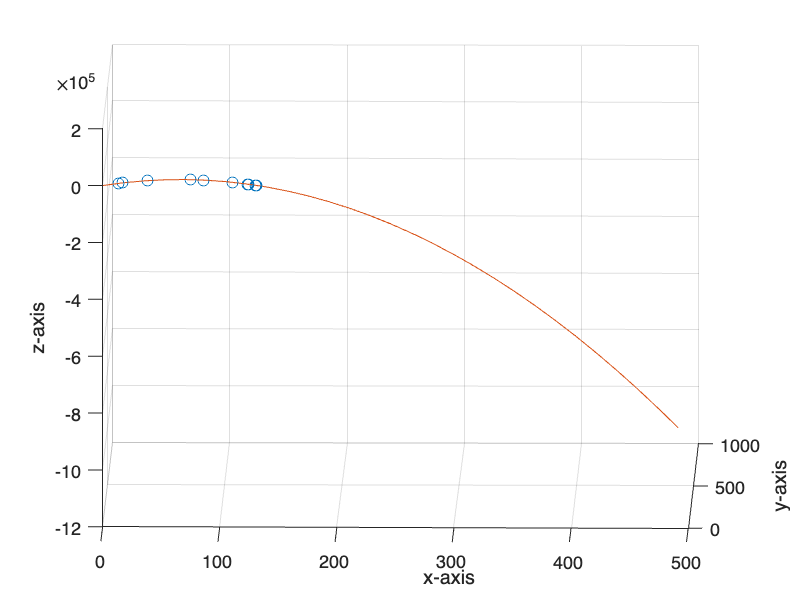




scatter3(fx,fy,fz)
%These are the sample points from which the curve is to be predicted

hold on

fplot3(xt,yt,zt,[0,36])
plot3(0,0,0)

%This is the target curve which the program has to achieve using the above
%data.

xlabel("x-axis")
ylabel("y-axis")
zlabel("z-axis")
hold off

view([1 12])